# Template of Manipulator Short project: Skull tumor surgery

Authors: Pablo Montón Gimeno

Team:  L

Shared Link with the teacher: 

I spect: 1) Pdf file, 2) Videos demostrating your successful task and your mlx file.

Notes. For better undestanding you can split the videos in the meaninful task.

Remember use the options of serial/link plot: 

'workspace' for centering in the surgery task

'zoom' ...  nice puma ratio aspect

'trail'  .. to see the trajectory

etc..

See all at:

>> help SerialLink/plot

## The Robotic environment (10%)

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

Use: 'c = uisetcolor' to chose your prefered colors

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: Vertices and Faces and use  'patch'  functions to model it. See help patch to find and example.

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

**Expected results**

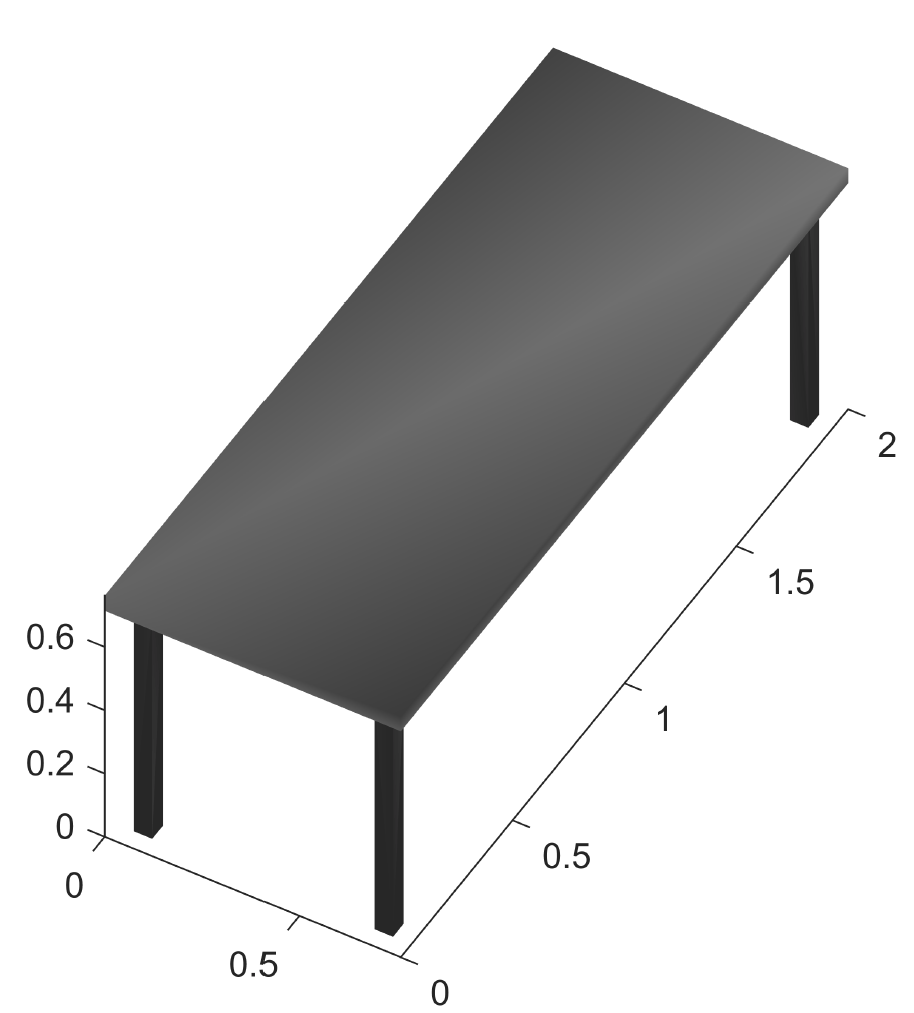

## put your code Here

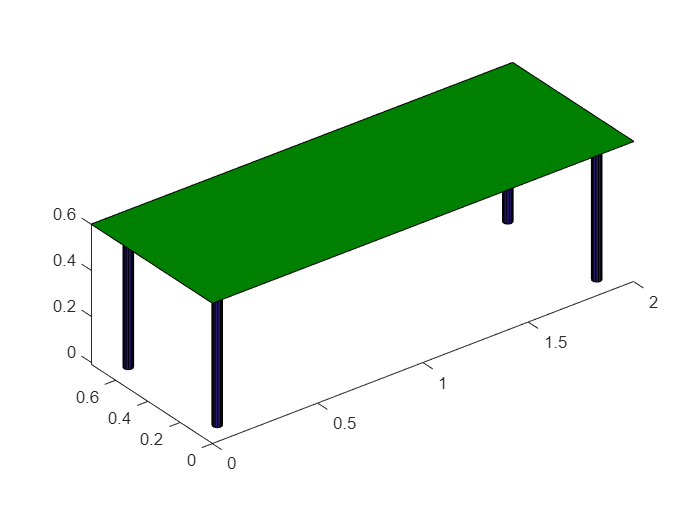

clear
clf
v = [0 0 0.6; 0 0.75 0.6; 2 0.75 0.6; 2 0 0.6];
f = [1 2 3 4];
view(3)
patch('Faces',f,'Vertices',v,'FaceColor',[0 0.5 0])
r = 0.02;
[X,Y,Z] = cylinder(r);
h = 0.6;
Z = Z*h-0.01;
hold on
surf(X+0.1,Y+0.1,Z)
surf(X+0.1,Y+0.65,Z)
surf(X+1.9,Y+0.1,Z)
surf(X+1.9,Y+0.65,Z)

axis equal

### 3D model of a human body 

Situate the human model on the operating table. 

**Expected results**

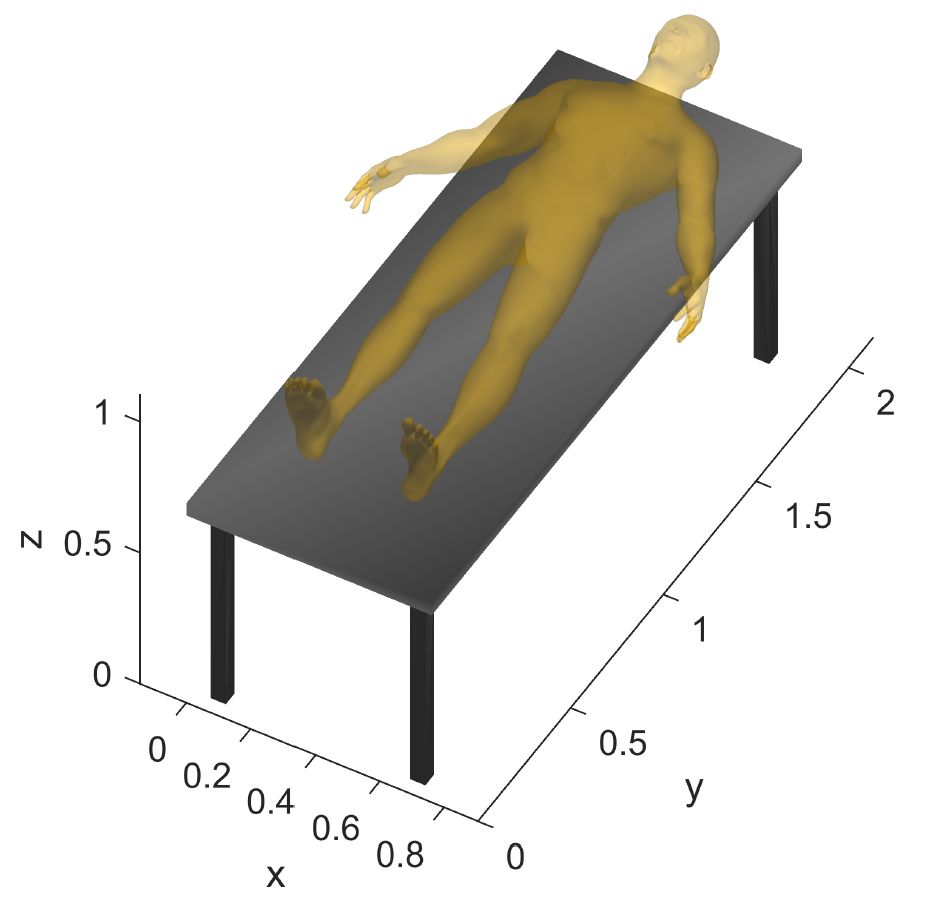

## put your code Here


load('F_V_HumanBody.mat')
view(3)
Vh(:,4) = 1;
Vh1 = transl(0.45,0.375,0.77)*trotz(-pi/2)*trotx(-pi/2)*Vh'

Vh1 =     1.7610    1.7649    1.7738    1.7706    1.7789    1.7786    1.7805    1.7844    1.7881    1.7919    1.7961    1.8000    1.7864    1.7948    1.7972    1.8035    1.8068    1.8125    1.8165    1.8214    1.8262    1.8301    1.8359    1.8312    1.8206    1.8419    1.8245    1.8316    1.8383    1.8167    1.8452    1.8084    1.8042    1.8121    1.8100    1.7996    1.7909    1.7894    1.8019    1.7879    1.7792    1.7787    1.7799    1.8131    1.8159    1.8039    1.7922    1.7693    1.7580    1.7589
    0.4893    0.5018    0.4941    0.4857    0.4896    0.4833    0.4987    0.4912    0.5016    0.4930    0.5037    0.4948    0.4831    0.4840    0.4743    0.4853    0.4753    0.4869    0.4768    0.4889    0.4789    0.4912    0.4814    0.4684    0.4663    0.4710    0.5003    0.5027    0.4941    0.4983    0.4846    0.4965    0.5054    0.5068    0.4649    0.4640    0.4530    0.4637    0.4532    0.4739    0.4641    0.4743    0.4533    0.4541    0.4432    0.4425    0.4422    0.4759    0.4667   

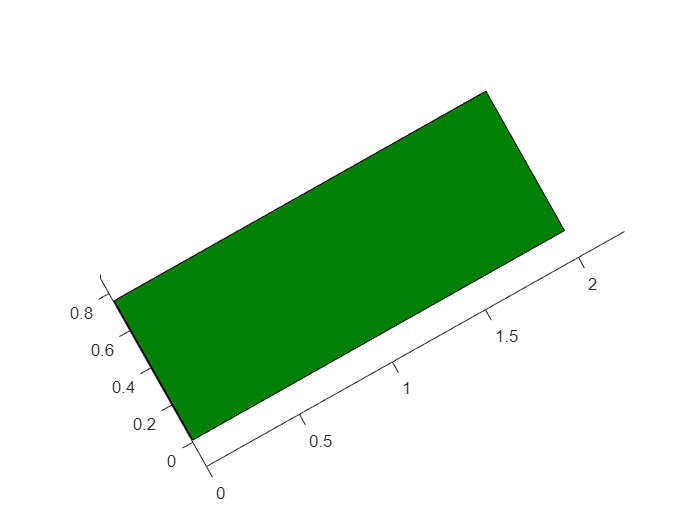

patch('Vertices',Vh1(1:3,:)','Faces',Fh,'FaceColor', [0.82 0.64 0.52], 'EdgeColor' , 'none', 'FaceAlpha', 0.8, 'FaceLighting',    'none')
axis equal

view([-29.413 89.040])

### Fiducials

The Radiology Department before to take a Computer Tomography (CT) of the brain, fix three fiducials in the head of the patient for registering purpose,  visit: [https://en.wikipedia.org/wiki/Fiducial](https://en.wikipedia.org/wiki/Fiducial)

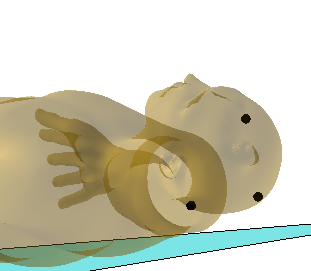

### Dicom image vs Image Reference frame {I}

Get familiar with Dicom Images, Visit: https://www.imaios.com/en/Imaios-Dicom-Viewer#!

Use a container Box of the skull  to infer the Image Reference Frame {I}

See:  6_Plot_Box_Cone.mlx and 7_Help_Image_RF_Containig_Box.fig to inspire yourselt 

**Expected results**

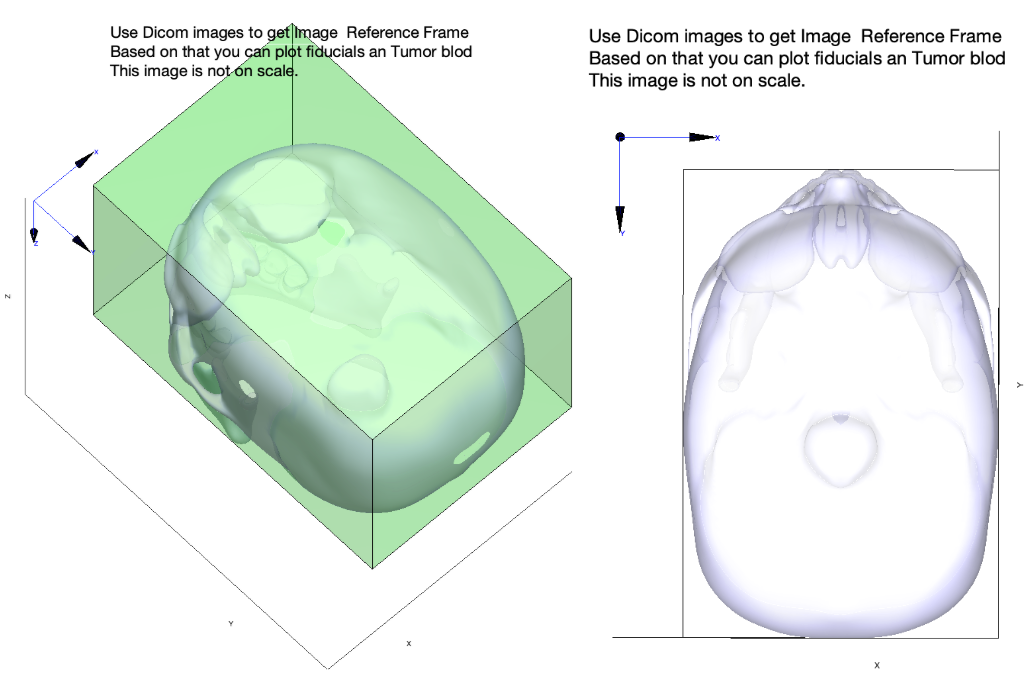

## put your code Here

clear
clf
load('F_V_Skull.mat')
view(3)
camlight headlight;
patch('Vertices',Vs,'Faces',Fs,'FaceColor', [0.5 0.5 0.5], 'EdgeColor' , 'none','FaceAlpha', 0.6,'BackFaceLighting','lit','AmbientStrength', 0.8)
%,'FaceColor', [0.5 0.5 0.5], 'EdgeColor' , 'none','FaceAlpha', 0.7
axis equal
max = max(Vs)

max =     0.0765    0.1077    0.2127


min = min(Vs)

min =    -0.0765   -0.1194    0.0004


maxX = max(1)

maxX = 0.0765

maxY = max(2)

maxY = 0.1077

maxZ = max(3)

maxZ = 0.2127

minX = min(1)

minX = -0.0765

minY = min(2)

minY = -0.1194

minZ = 0.072

minZ = 0.0720

v= [minX minY minZ;maxX minY minZ;maxX maxY minZ;minX maxY minZ;minX minY maxZ;maxX minY maxZ;maxX maxY maxZ;minX maxY maxZ]

v =    -0.0765   -0.1194    0.0720
    0.0765   -0.1194    0.0720
    0.0765    0.1077    0.0720
   -0.0765    0.1077    0.0720
   -0.0765   -0.1194    0.2127
    0.0765   -0.1194    0.2127
    0.0765    0.1077    0.2127
   -0.0765    0.1077    0.2127


f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


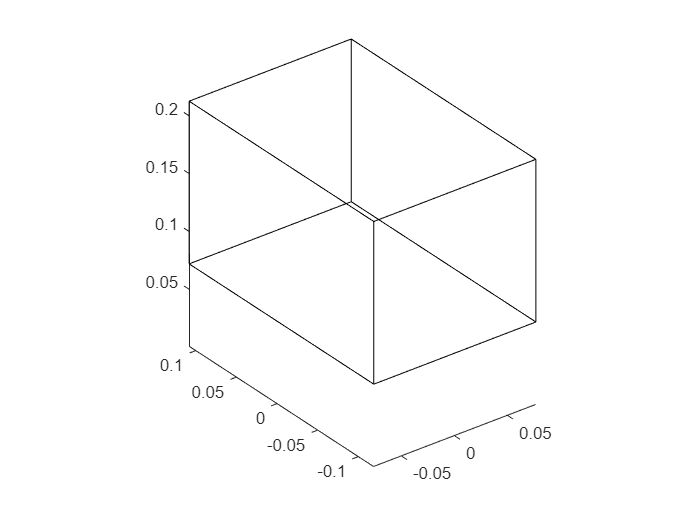

patch('Vertices',v,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.1)

altura = maxZ-minZ

altura = 0.1407

ancho = maxY-minY

ancho = 0.2271

hondo=maxX-minX

hondo = 0.1530

### Fiducials wrt {I}

Use the Dicom images to place the fiducial relative to Image Reference Frame {I}.

See: 5_Skull_pose_estimation.mlx and use the skull to make the exercise.

**Expected results**

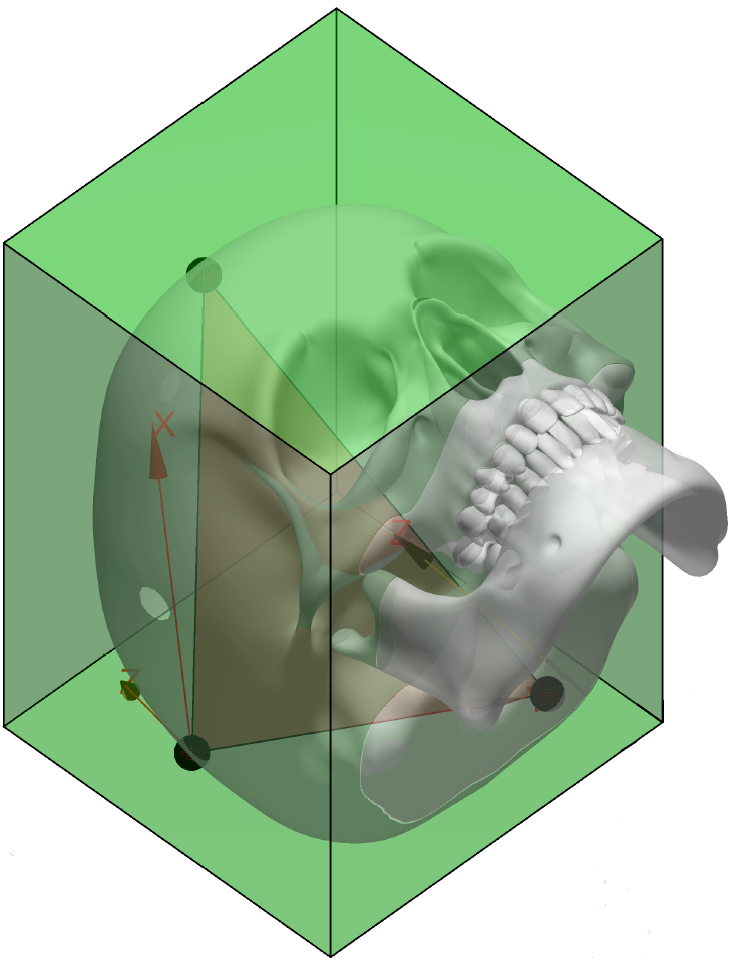

## put your code Here

%pFid1 = [122*1.4 61 94]
%pFid2 = [185*1.4 209 65]
%pFid3 = [71*1.4 212 32]

%mmmaxXDicom = 222 
%mmmaxYDicom = 256
%mmDicomAltura = 112 * 1.4
%dicom -> matlab
%digits(6)
%mmX = vpa(altura/mmDicomAltura)
%mmY = mmX
%mmZ = mmX

%Centro craneo
%XcenterSkull = minX + (difX/2)
%YcenterSkull = minY + (ancho/2)
%ZcenterSkull = minZ 
%Centro craneo
%centerSkull = [centerSkullX, centerSkullY, centerSkullZ]

%Xorig = XcenterSkull - (XcenterSkull * mmX)
%Yorig = YcenterSkull - (YcenterSkull * mmY)
%Zorig = ZcenterSkull
%digits(4)
%orig = vpa([Xorig,Yorig,Zorig])
%pFid1 = [122*1.4 61 94]
%pFid2 = [185*1.4 209 65]
%pFid3 = [71*1.4 212 32]

%pFid1(1) = (pFid1(1) * mmX) + orig(1)
%pFid1(2) = (pFid1(2) * mmY) + orig(2)
%pFid1(3) = (pFid1(3) * mmZ) + orig(3)

%pFid2(1) = (pFid2(1) * mmX) + orig(1)
%pFid2(2) = (pFid2(2) * mmY) + orig(2)
%pFid2(3) = (pFid2(3) * mmZ) + orig(3)

%pFid3(1) = (pFid3(1) * mmX) + orig(1)
%pFid3(2) = (pFid3(2) * mmY) + orig(2)
%pFid3(3) = (pFid3(3) * mmZ) + orig(3)
%hold on
%plot(pFid1*mmX,'.')

maxDicomX = 222

maxDicomX = 222

maxDicomY = 256

maxDicomY = 256

maxDicomZ = 112*1.4

maxDicomZ = 156.8000


%Dicom to Matlab
mmDicMat = altura/maxDicomZ

mmDicMat = 8.9703e-04

centerSkullX = minX + ((maxX-minX)/2)

centerSkullX = -1.9279e-06

centerSkullY = minY + ((maxY-minY) / 2)

centerSkullY = -0.0059

centerSkullZ = minZ + ((maxZ-minZ) / 2)

centerSkullZ = 0.1423

altura

altura = 0.1407

hondo

hondo = 0.1530

ancho

ancho = 0.2271

minZ

minZ = 0.0720

minY

minY = -0.1194

minX

minX = -0.0765

centerSkull = [centerSkullX, centerSkullY, centerSkullZ]

centerSkull =    -0.0000   -0.0059    0.1423


centerSkull

centerSkull =    -0.0000   -0.0059    0.1423


hold on
%scatter3(centerSkullX, centerSkullY,centerSkullZ)
minXDic = 41

minXDic = 41

maxXDic = 206

maxXDic = 206

minYDic = 27

minYDic = 27

maxYDic = 234

maxYDic = 234

centerDicomX = minXDic + ((maxXDic-minXDic) / 2)

centerDicomX = 123.5000

centerDicomY = minYDic + ((maxYDic-minYDic) / 2)

centerDicomY = 130.5000

centerDicomZ = maxDicomZ / 2

centerDicomZ = 78.4000

dicomToSkullX = (maxX - minX) / (maxXDic-minXDic) 

dicomToSkullX = 9.2727e-04

%dicomToSkullX = maxX / (maxXDic) * 2
dicomToSkullY = (maxY - minY) / (maxYDic - minYDic) 

dicomToSkullY = 0.0011

%dicomToSkullY = maxY / (maxYDic) * 2
dicomToSkullZ = (maxZ-minZ) / maxDicomZ

dicomToSkullZ = 8.9703e-04


%Fiducials
pFid1 = [122-centerDicomX 61-centerDicomY (94*1.4)]

pFid1 =    -1.5000  -69.5000  131.6000


pFid2 = [185-centerDicomX 209-centerDicomY (65*1.4)]

pFid2 =    61.5000   78.5000   91.0000


pFid3 = [71-centerDicomX 212-centerDicomY (32*1.4)]

pFid3 =   -52.5000   81.5000   44.8000



pSFid1 = [pFid1(1)*dicomToSkullX pFid1(2)*dicomToSkullY pFid1(3)*dicomToSkullZ]

pSFid1 =    -0.0014   -0.0763    0.1180


pSFid2 = [pFid2(1)*dicomToSkullX pFid2(2)*dicomToSkullY pFid2(3)*dicomToSkullZ]

pSFid2 =     0.0570    0.0861    0.0816


pSFid3 = [pFid3(1)*dicomToSkullX pFid3(2)*dicomToSkullY pFid3(3)*dicomToSkullZ]

pSFid3 =    -0.0487    0.0894    0.0402


v2= [minXDic minYDic 0;maxXDic minYDic 0;maxXDic maxYDic 0;minXDic maxYDic 0;minXDic minYDic maxDicomZ;maxXDic minYDic maxDicomZ;maxXDic maxYDic maxDicomZ;minXDic maxYDic maxDicomZ]

v2 =    41.0000   27.0000         0
  206.0000   27.0000         0
  206.0000  234.0000         0
   41.0000  234.0000         0
   41.0000   27.0000  156.8000
  206.0000   27.0000  156.8000
  206.0000  234.0000  156.8000
   41.0000  234.0000  156.8000


f2 = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f2 =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


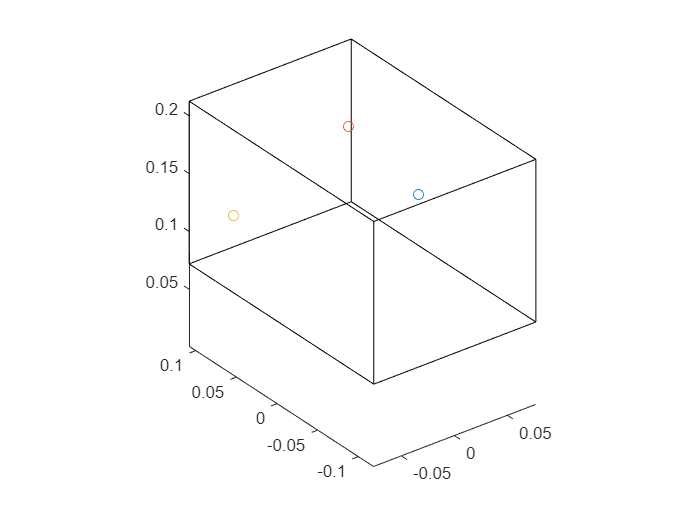

hold on
scatter3(pSFid1(1), pSFid1(2) ,pSFid1(3)+minZ)
scatter3(pSFid2(1), pSFid2(2) ,pSFid2(3)+minZ)
scatter3(pSFid3(1), pSFid3(2) ,pSFid3(3)+minZ)

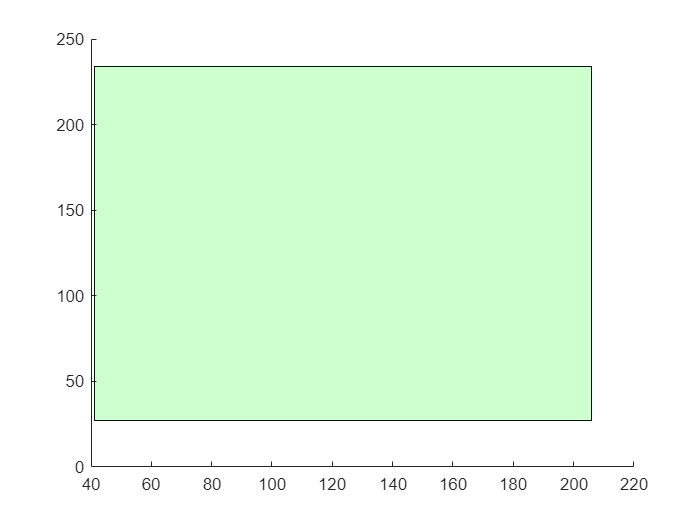

clf
patch('Vertices',v2,'Faces',f2,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.1)

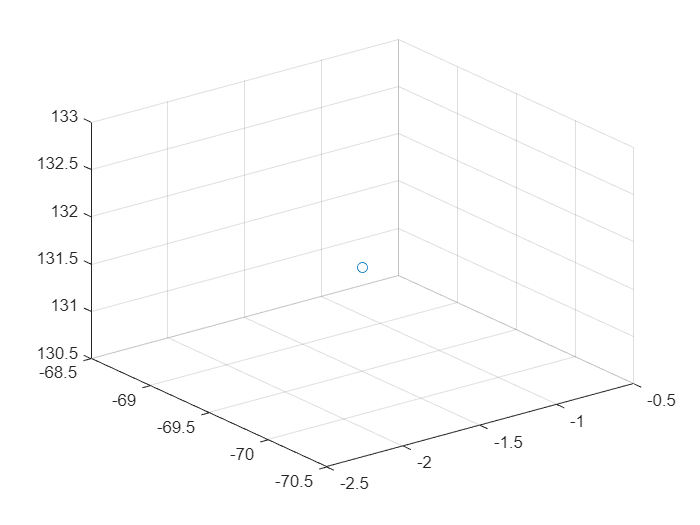

scatter3(pFid1(1), pFid1(2) ,pFid1(3))

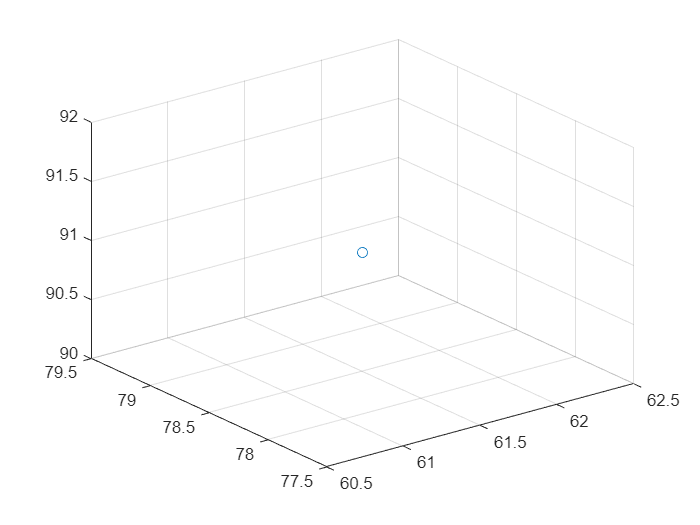

scatter3(pFid2(1), pFid2(2) ,pFid2(3))

%scatter3(pFid3(1), pFid3(2) ,pFid3(3))
maxDicomX

maxDicomX = 222

maxXDic

maxXDic = 206

maxXDic * dicomToSkullX

ans = 0.1910

122*dicomToSkullX

ans = 0.1131

maxXDic-122

ans = 84

maxX

maxX = 0.0765

maxY

maxY = 0.1077

### Tumor points wrt {I}

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

You can simplify the tumor information by defining the center of mass and estimate an equivalent diameter.

**Expected results**

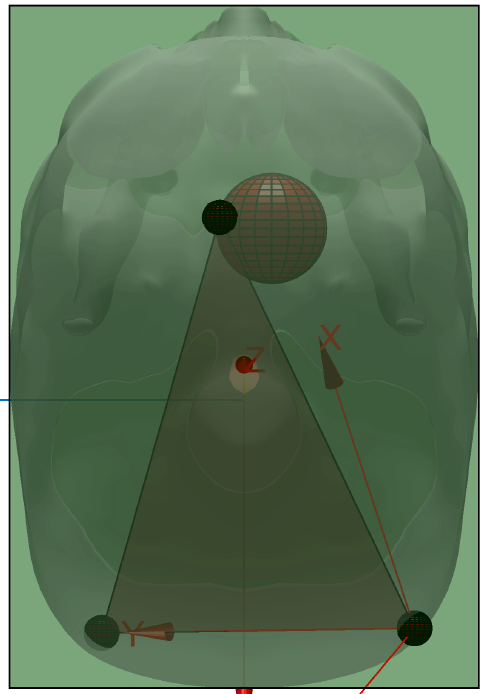

%% put your code Here

### Fiducials and Tumor wrt Human Reference Frame

Place fiducial and tumor in the head of the human. You will have to re-do the containing box secction.

**Expected results**

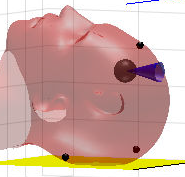

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560. Use p560.teach to play.

Use: p560.base & p560.tool to locate the Puma and add the tools.

**Expected results**

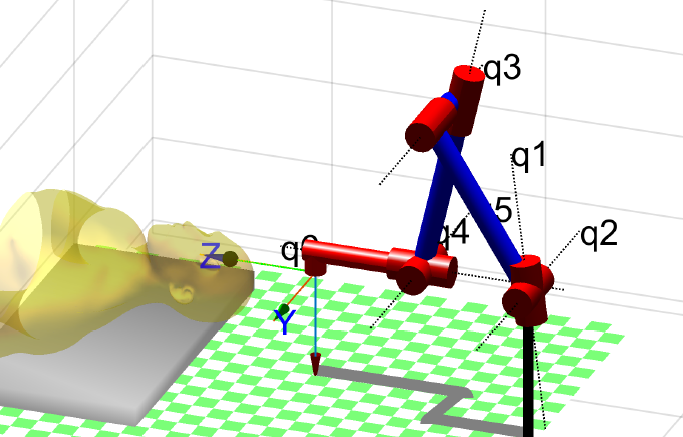

%% put your code Here

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

- others

- ...

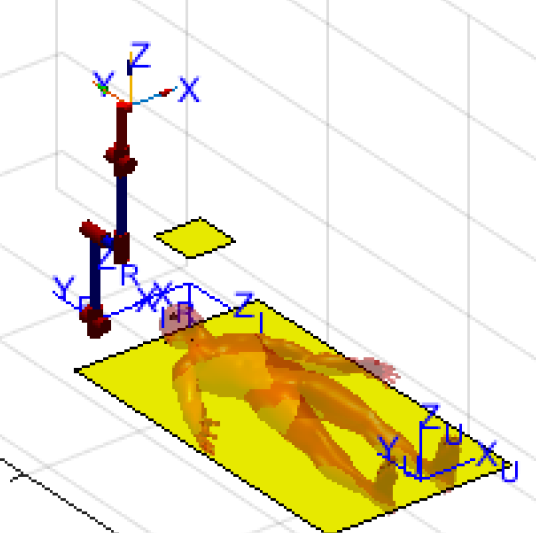

%% put your code Here

### Transformations

Enumerate the transformation you will need.

%% put your code Here

### Tumor points in Robot Frame.

Remember the Transform compound exercise

%% put your code Here


## *Second approach: ( 25%)*

Modify your code  to repeat the exercise if  the table with the patient is given as happend in the Rosa video.

To know the head relative pose with respect to the Puma Robot ...

*See:  **‘4_Sckeching_Key_ideas_students.mlx’ , ‘5_Skull_pose estimation.mlx’ for inspiration and Second_approach_SPM.pdf*

open('3_Second_approach_Patient_pose.fig')

## Surgery (55%)

### Biospy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0.05 0 0.25)

Let us see the 'trail' option of plot to visualize the trajectory.

%% put your code Here

### Trepanation

Prepare a script that perform trepanation. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0 0 0.2)

Let us see the 'trail' option of plot to visualize the trajectory. Place a 45º cone on top of the trepanation to better understand. See: 6_Plot_Box_Cone.mlx. You will have to scale it. Play with transparency.

%% put your code Here

### Tumor burning

Prepare a script that perform tumor burning with the laser.  Zoom in the scene and record a video with the best view.

You ought to think in an algorithm, that in order, fill up the tumor's  equivalent sphere with small burning spheres of 4m diameter.

Use a tool that has the following Transformation: transl(0 0 0.2)

%% put your code Here